# **The Capital Asset Pricing Model**

**1. Foundations in Portfolio Theory**

The origins of CAPM can be traced back to the work of Harry Markowitz, who in 1952 introduced the concept of portfolio theory in his seminal paper "Portfolio Selection." Markowitz's theory emphasized the importance of diversification and showed how investors could construct portfolios to optimize or maximize expected return based on a given level of market risk. This work laid the groundwork for the development of more advanced asset pricing models by introducing key concepts such as:

- **Risk-Return Tradeoff:** The idea that higher returns come with higher risk.

- **Efficient Frontier:** A set of optimal portfolios offering the highest expected return for a defined level of risk.

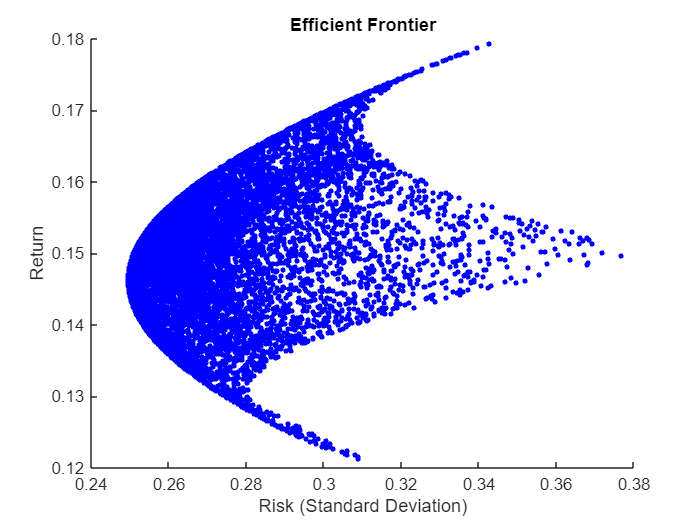

% Sample data: Expected returns and covariance matrix for three assets
expected_returns = [0.12, 0.18, 0.15]; % Expected returns of the assets
cov_matrix = [0.1, 0.02, 0.04; 0.02, 0.12, 0.06; 0.04, 0.06, 0.15]; % Covariance matrix

% Number of assets
n_assets = length(expected_returns);

% Generate random portfolios
n_portfolios = 10000;
weights = rand(n_portfolios, n_assets);
weights = weights ./ sum(weights, 2); % Ensure the weights sum to 1

% Calculate portfolio returns and risks
portfolio_returns = weights * expected_returns';
portfolio_risks = zeros(n_portfolios, 1);
for i = 1:n_portfolios
    portfolio_risks(i) = sqrt(weights(i, :) * cov_matrix * weights(i, :)');
end

% Plot the random portfolios
figure;
scatter(portfolio_risks, portfolio_returns, 10, 'b', 'filled');
xlabel('Risk (Standard Deviation)');
ylabel('Return');
title('Efficient Frontier');
hold on;

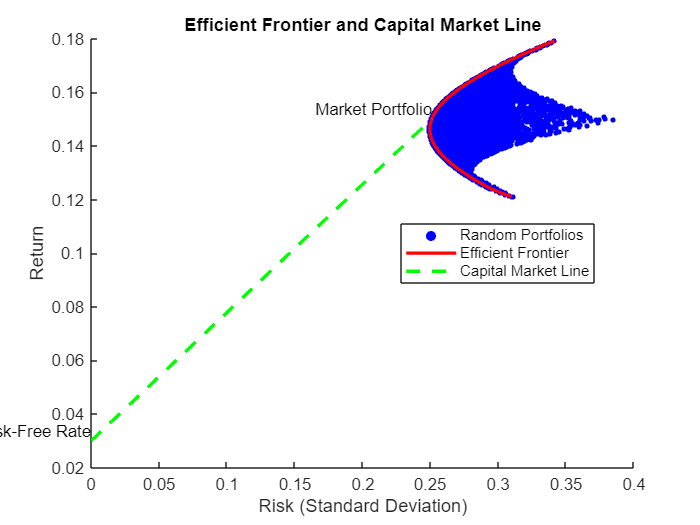


% Sample data: Expected returns and covariance matrix for three assets
expected_returns = [0.12, 0.18, 0.15]; % Expected returns of the assets
cov_matrix = [0.1, 0.02, 0.04; 0.02, 0.12, 0.06; 0.04, 0.06, 0.15]; % Covariance matrix

% Number of assets
n_assets = length(expected_returns);

% Generate random portfolios
n_portfolios = 10000;
weights = rand(n_portfolios, n_assets);
weights = weights ./ sum(weights, 2); % Ensure the weights sum to 1

% Calculate portfolio returns and risks
portfolio_returns = weights * expected_returns';
portfolio_risks = zeros(n_portfolios, 1);
for i = 1:n_portfolios
    portfolio_risks(i) = sqrt(weights(i, :) * cov_matrix * weights(i, :)');
end

% Calculate the efficient frontier using quadratic programming
return_targets = linspace(min(portfolio_returns), max(portfolio_returns), 100);
efficient_risks = zeros(size(return_targets));
efficient_weights = zeros(length(return_targets), n_assets);

options = optimset('Display', 'off');
for i = 1:length(return_targets)
    Aeq                     = [ones(1, n_assets); expected_returns];
    beq                     = [1; return_targets(i)];
    f                       = zeros(1, n_assets);
    efficient_weights(i, :) = quadprog(cov_matrix, f, [], [], Aeq, beq, zeros(1, n_assets), ones(1, n_assets), [], options);
    efficient_risks(i)      = sqrt(efficient_weights(i, :) * cov_matrix * efficient_weights(i, :)');
end

% Plot the efficient frontier and random portfolios
figure;
scatter(portfolio_risks, portfolio_returns, 10, 'b', 'filled');
xlabel('Risk (Standard Deviation)');
ylabel('Return');
title('Efficient Frontier and Capital Market Line');
hold on;
plot(efficient_risks, return_targets, 'r-', 'LineWidth', 2);

% Add the Capital Market Line (CML)
risk_free_rate = 0.03; % Assume a risk-free rate of 3%
market_portfolio = mean(efficient_weights, 1); % Mean weights for the market portfolio
market_return = market_portfolio * expected_returns';
market_risk = sqrt(market_portfolio * cov_matrix * market_portfolio');

cml_x = [0, market_risk];
cml_y = [risk_free_rate, market_return];
plot(cml_x, cml_y, 'g--', 'LineWidth', 2);

% Add labels
legend('Random Portfolios', 'Efficient Frontier', 'Capital Market Line', 'Location', 'Best');
text(market_risk, market_return, ' Market Portfolio', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
text(0, risk_free_rate, ' Risk-Free Rate', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');

hold off;

**2. Development of CAPM**

Building on Markowitz’s work, several economists further developed the theory, leading to the creation of the CAPM. The key contributors to the development of CAPM include:

- **William F. Sharpe:** In 1964, Sharpe published "Capital Asset Prices: A Theory of Market Equilibrium under Conditions of Risk," which formally introduced CAPM. He demonstrated how to price risky assets by relating their expected returns to their risk relative to the overall market.

- **John Lintner:** Simultaneously, Lintner published similar findings in his papers in 1965. He provided a slightly different but complementary approach to the model.

- **Jan Mossin:** Also in 1966, Mossin contributed to the formalization of CAPM independently.

These researchers collectively showed that the expected return on an asset is linearly related to its beta, a measure of the asset's sensitivity to market movements. The model posits that the expected return on an asset is equal to the risk-free rate plus the asset's beta times the market risk premium.

% Sample data: Monthly returns for three factors
months = 60;
rf = 0.001; % Monthly risk-free rate
market_returns = 0.01 + 0.04 * randn(months, 1); % Market returns
smb_returns = 0.02 + 0.05 * randn(months, 1); % SMB returns
hml_returns = 0.015 + 0.03 * randn(months, 1); % HML returns

% Portfolio returns
beta = 1.2;
s = 0.5;
h = 0.3;
portfolio_returns = rf + beta * (market_returns - rf) + s * smb_returns + h * hml_returns + 0.02 * randn(months, 1);

% CAPM regression
X_capm = [ones(months, 1), market_returns - rf];
b_capm = regress(portfolio_returns - rf, X_capm);

% Fama-French regression
X_ff = [ones(months, 1), market_returns - rf, smb_returns, hml_returns];
b_ff = regress(portfolio_returns - rf, X_ff);

% Display results
fprintf('CAPM Regression Coefficients:\n');

CAPM Regression Coefficients:


fprintf('Alpha: %.4f\n', b_capm(1));

Alpha: 0.0110


fprintf('Beta: %.4f\n', b_capm(2));

Beta: 1.3664



fprintf('\nFama-French Regression Coefficients:\n');


Fama-French Regression Coefficients:


fprintf('Alpha: %.4f\n', b_ff(1));

Alpha: 0.0018


fprintf('Beta: %.4f\n', b_ff(2));

Beta: 1.2393


fprintf('s (SMB): %.4f\n', b_ff(3));

s (SMB): 0.4578


fprintf('h (HML): %.4f\n', b_ff(4));

h (HML): 0.1168


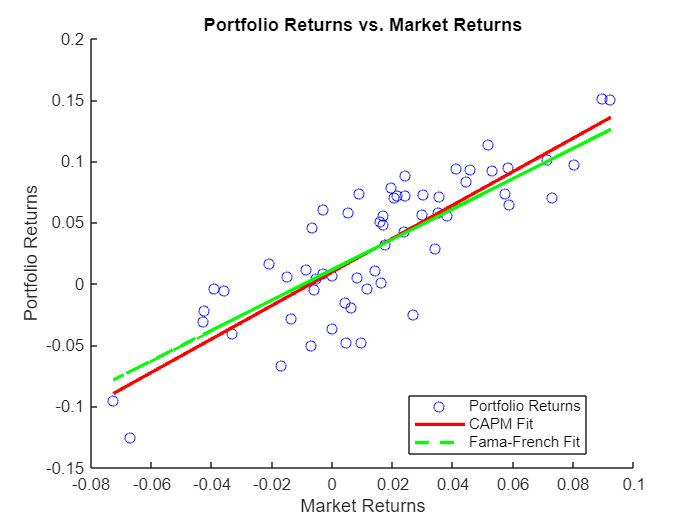


% Plotting the results
figure;
hold on;

% Scatter plot of portfolio returns vs. market returns
scatter(market_returns, portfolio_returns, 'b');

% Plot CAPM regression line
capm_line = b_capm(1) + b_capm(2) * (market_returns - rf);
plot(market_returns, capm_line, 'r-', 'LineWidth', 2);

% Calculate Fama-French regression line for the average SMB and HML returns
avg_smb = mean(smb_returns);
avg_hml = mean(hml_returns);
ff_line = b_ff(1) + b_ff(2) * (market_returns - rf) + b_ff(3) * avg_smb + b_ff(4) * avg_hml;
plot(market_returns, ff_line, 'g--', 'LineWidth', 2);

% Labels and legend
xlabel('Market Returns');
ylabel('Portfolio Returns');
title('Portfolio Returns vs. Market Returns');
legend('Portfolio Returns', 'CAPM Fit', 'Fama-French Fit', 'Location', 'Best');

hold off;

**3. Key Contributions and Implications**

The CAPM brought several key insights to financial economics:

- **Systematic vs. Unsystematic Risk:** CAPM distinguishes between systematic risk (market risk) and unsystematic risk (specific to individual assets). According to the model, only systematic risk is rewarded because unsystematic risk can be diversified away.

- **Beta:** The model introduced the concept of beta as a measure of an asset's market-related risk. A beta greater than one indicates more volatility than the market, while a beta less than one indicates less.

- **Security Market Line (SML):** CAPM describes the relationship between the expected return of an asset and its beta, graphically represented by the Security Market Line. The SML shows that assets are priced such that their expected returns are proportional to their betas.

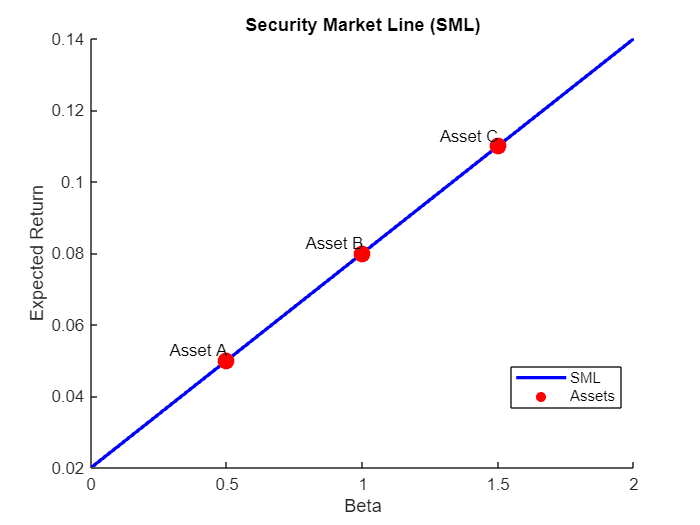

% Assumptions
risk_free_rate = 0.02;
market_return = 0.08;
market_premium = market_return - risk_free_rate; % Market risk premium

% Asset betas
betas = [0.5, 1.0, 1.5];

% Calculate expected returns using CAPM
expected_returns = risk_free_rate + betas * market_premium;

% Plot the SML
figure;
hold on;

% Plot the SML line
sml_betas = linspace(0, 2, 100);
sml_returns = risk_free_rate + sml_betas * market_premium;
plot(sml_betas, sml_returns, 'b-', 'LineWidth', 2);

% Plot the assets
scatter(betas, expected_returns, 100, 'r', 'filled');

% Add labels and titles
xlabel('Beta');
ylabel('Expected Return');
title('Security Market Line (SML)');
legend('SML', 'Assets', 'Location', 'Best');

% Add text annotations for the assets
text(betas(1), expected_returns(1), '  Asset A', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
text(betas(2), expected_returns(2), '  Asset B', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
text(betas(3), expected_returns(3), '  Asset C', 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');

hold off;

**4. Empirical Testing and Critiques**

Since its inception, CAPM has been extensively tested and critiqued. Empirical tests have shown mixed results, with some supporting the model's predictions and others highlighting anomalies and limitations. Critics argue that CAPM's assumptions, such as a single-period investment horizon and identical investor expectations, are unrealistic. Despite these critiques, CAPM remains a foundational model in finance for understanding risk and return.

**5. Extensions and Alternatives**

In response to the limitations of CAPM, various extensions and alternative models have been developed, including:

- **Arbitrage Pricing Theory (APT):** Proposed by Stephen Ross in 1976, APT provides a multi-factor model to explain asset returns, addressing some of the limitations of CAPM.

- **Fama-French Three-Factor Model:** Introduced by Eugene Fama and Kenneth French in 1992, this model adds size and value factors to the market risk factor, offering a more comprehensive explanation of asset returns.

**6. Continuing Relevance**

Despite its limitations and the development of alternative models, CAPM continues to be widely used in practice. It serves as a cornerstone in finance education and is a standard tool for assessing the risk and return of investments, informing asset pricing, and guiding investment decisions.

CAPM's historical context highlights its pivotal role in the evolution of financial theory and its enduring influence on the understanding of risk and return in financial markets.

% Sample data: monthly returns for portfolio and benchmark
returns_portfolio = [0.02, 0.03, 0.01, -0.01, 0.04];
returns_benchmark = [0.015, 0.025, 0.005, -0.005, 0.035];
risk_free_rate = 0.01 / 12; % Monthly risk-free rate

% Calculate excess returns
excess_returns_portfolio = returns_portfolio - risk_free_rate;
excess_returns_benchmark = returns_benchmark - risk_free_rate;

% Regression to calculate beta
X = [ones(length(excess_returns_benchmark), 1), excess_returns_benchmark'];
b = regress(excess_returns_portfolio', X);
beta_portfolio = b(2);

% Expected return using CAPM
expected_return_portfolio = risk_free_rate + beta_portfolio * (mean(returns_benchmark) - risk_free_rate);

% Actual return of the portfolio
actual_return_portfolio = mean(returns_portfolio);

% Calculate alpha
alpha_portfolio = actual_return_portfolio - expected_return_portfolio;

% Display results
fprintf('Beta of Portfolio: %.2f\n', beta_portfolio);

Beta of Portfolio: 1.20


fprintf('Expected Return of Portfolio: %.2f\n', expected_return_portfolio);

Expected Return of Portfolio: 0.02


fprintf('Actual Return of Portfolio: %.2f\n', actual_return_portfolio);

Actual Return of Portfolio: 0.02


fprintf('Alpha of Portfolio: %.2f\n', alpha_portfolio);

Alpha of Portfolio: 0.00


**What causes alpha?**

**    Market Timing:**

- The ability of the portfolio manager to anticipate market movements and adjust the portfolio accordingly.

- For example, shifting between cash and equities based on market conditions could result in returns that are not explained by static sector allocation or stock selection.

**    Skill or Luck:**

- Alpha could reflect the manager's skill in picking securities or timing the market, which goes beyond the systematic allocation and selection effects.

- Alternatively, it could also result from random chance or luck, especially over short time periods.

**    Transaction Costs:**

- Trading costs, such as brokerage fees, bid-ask spreads, and market impact costs, can affect the portfolio's returns.

- These costs are not typically captured in the allocation or selection effects but impact the overall return.

**    Idiosyncratic Risk:**

- Specific risks associated with individual securities that are not captured by the broader sector or market factors.

- Events such as corporate actions, earnings surprises, or regulatory changes affecting specific companies can contribute to idiosyncratic risk.

**    Model Limitations:**

- The Brinson model assumes a linear relationship between sector weights and returns, and any nonlinear effects or interactions between sectors are not captured.

- The model also assumes that the benchmark is appropriate and accurately reflects the investment environment. Deviations from this assumption can lead to unexplained returns.

**    Benchmark Misalignment:**

- Differences between the benchmark's characteristics and the actual investment strategy of the portfolio.

- If the benchmark does not accurately represent the investment universe or style of the portfolio, the residual return might be significant.

**    Currency Effects:**

- For portfolios with international investments, fluctuations in currency exchange rates can affect returns.

- These currency effects are often not included in the sector-based attribution analysis.

**    Other Factors:**

- Changes in macroeconomic conditions, geopolitical events, or shifts in investor sentiment can also contribute to unexplained returns.

- These factors might not be directly related to the sectors or securities chosen but can impact overall market conditions.